# 3.1

## Minimun phase

## 3.1.1

sysmp = minphase;
s=tf('s');
G=(sysmp.C/(s*eye(size(sysmp.A))-sysmp.A))*sysmp.B+sysmp.D;
G=minreal(G);

Poles for elements in G

% Poles for elements
pole(G(1,1));
pole(G(1,2));
pole(G(2,1));
pole(G(2,2));

Zeros for elements in G

% Zeros for elements
tzero(G(1,1));
tzero(G(1,2));
tzero(G(2,1));
tzero(G(2,2));

## 3.1.2

Poles for system G

% Poles for system
pole(G);

Zeros for system G

%Zeros for system
tzero(G);

## 3.1.3

Singular values for the system at different frequencies

sv=sigma(G);

H_inf for the system

H_inf=norm(G,inf);

## 3.1.4

s=0;
G_zero=(sysmp.C/(s*eye(size(sysmp.A))-sysmp.A))*sysmp.B+sysmp.D;
RGA=G_zero.*inv(G_zero)';

Negative elements in G_zero, Not good!!!!

## 3.1.5

Step response for each input/output

step(G);

Yes it is coupled

## Non-minimum Phase

## 3.1.1

sysmp = nonminphase;
s=tf('s');
G=(sysmp.C/(s*eye(size(sysmp.A))-sysmp.A))*sysmp.B+sysmp.D;
G=minreal(G);

Poles for elements in G

% Poles for elements
pole(G(1,1));
pole(G(1,2));
pole(G(2,1));
pole(G(2,2));

Zeros for elements in G

% Zeros for elements
tzero(G(1,1));
tzero(G(1,2));
tzero(G(2,1));
tzero(G(2,2));

## 3.1.2

Poles for system G

% Poles for system
pole(G);

Zeros for system G

%Zeros for system
tzero(G);

## 3.1.3

Singular values for the system at different frequencies

sv=sigma(G);

H_inf for the system

H_inf=norm(G,inf);

## 3.1.4

s=0;
G_zero=(sysmp.C/(s*eye(size(sysmp.A))-sysmp.A))*sysmp.B+sysmp.D;
RGA=G_zero.*inv(G_zero)';

Negative elements in G_zero, Not good!!!!

## 3.1.5

Step response for each input/output

step(G)

Yes it is coupled

# 3.2

## Minimum Phase

## 3.2.1

sysmp = minphase;
s=tf('s');
G=(sysmp.C/(s*eye(size(sysmp.A))-sysmp.A))*sysmp.B+sysmp.D;
G=minreal(G);

wc=0.1;
pm=(180/pi)*(pi/3);

f1

[~,p]=bode(G(1,1),wc);

T11=(tand(pm-p-90))/wc;
L11=G(1,1)*(1+(1/(s*T11)));
L11=minreal(L11);
[m,p]=bode(L11,wc);
K1=1/m;

f1=K1*(1+(1/(s*T11)));
f1=minreal(f1);

f2

[~,p]=bode(G(2,2),wc);

T22=(tand(pm-p-90))/wc;
L22=G(2,2)*(1+(1/(s*T22)));
L22=minreal(L22);
[m,p]=bode(L22,wc);
K2=1/m;

f2=K2*(1+(1/(s*T22)));
f2=minreal(f2);

L

F=[f1,0;0,f2];
L=G*F;
[m,p]=bode(L,wc)

m =     1.0000    0.1466
    0.1274    1.0000


p =  -120.0000 -193.5493
 -200.0048 -120.0000


## 3.2.2

S=inv(eye(2)+L);
S=minreal(S)


S =
 
  From input 1 to output...
       s^7 + 0.2724 s^6 + 0.03653 s^5 + 0.002747 s^4 + 0.0001114 s^3 + 2.205e-06 s^2 + 1.657e-08 s - 5.905e-25
   1:  -------------------------------------------------------------------------------------------------------
       s^7 + 0.3308 s^6 + 0.05903 s^5 + 0.006304 s^4 + 0.0004315 s^3 + 1.75e-05 s^2 + 3.373e-07 s + 1.857e-09
 
              -0.0007459 s^4 - 0.0001876 s^3 - 1.146e-05 s^2 - 1.834e-07 s - 2.546e-24
   2:  --------------------------------------------------------------------------------------
       s^6 + 0.2744 s^5 + 0.04354 s^4 + 0.003846 s^3 + 0.0002144 s^2 + 5.392e-06 s + 3.29e-08
 
  From input 2 to output...
              -0.0009362 s^4 - 0.000215 s^3 - 1.175e-05 s^2 - 1.618e-07 s + 2.246e-24
   1:  --------------------------------------------------------------------------------------
       s^6 + 0.2744 s^5 + 0.04354 s^4 + 0.003846 s^3 + 0.0002144 s^2 + 5.392e-06 s + 3.29e-08
 
       s^7 + 0.2656 s^6 + 0.03532 s^5 + 0.002606 s


T=inv(eye(2)+L)*L


T =
 
  From input 1 to output...
                                                                                                                                                       
        0.05838 s^24 + 0.05544 s^23 + 0.02545 s^22 + 0.007513 s^21 + 0.001593 s^20 + 0.0002566 s^19 + 3.238e-05 s^18 + 3.256e-06 s^17 + 2.631e-07 s^16 
                                                                                                                                                       
                + 1.71e-08 s^15 + 8.903e-10 s^14 + 3.674e-11 s^13 + 1.183e-12 s^12 + 2.906e-14 s^11 + 5.276e-16 s^10 + 6.756e-18 s^9 + 5.677e-20 s^8   
                                                                                                                                                       
                                                                         + 2.759e-22 s^7 + 5.788e-25 s^6 + 9.7e-41 s^5 - 2.67e-57 s^4 - 1.581e-73 s^3  
                                                     

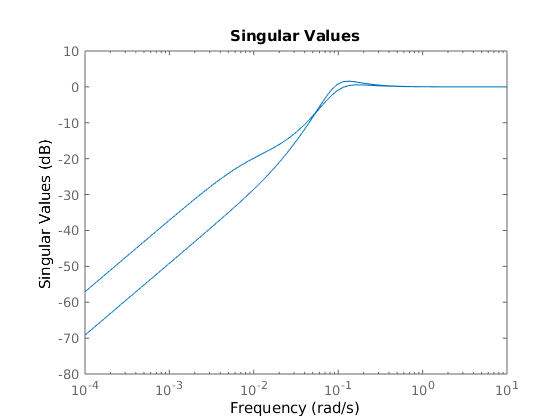

T=minreal(T);

sigma(S)

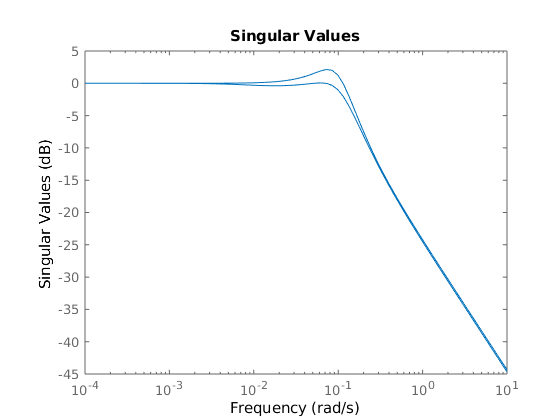

sigma(T)


stepinfo(T)

ans = 2×2 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime



%bode(T)
%hold on
%bode(S)
%hold off
%bode(S+T)

## 3.2.3

%closedloop 

## Non-Minimum Phase

## 3.2.1

sysmp = nonminphase;
s=tf('s');
G=(sysmp.C/(s*eye(size(sysmp.A))-sysmp.A))*sysmp.B+sysmp.D;
G=minreal(G);

wc=0.02;
pm=(180/pi)*(pi/3);

f1

[~,p]=bode(G(2,1),wc);

T12=(tand(pm-p-90))/wc;
L12=G(2,1)*(1+(1/(s*T12)));
L12=minreal(L12);
[m,p]=bode(L12,wc);
K1=1/m;

f1=K1*(1+(1/(s*T12)));
f1=minreal(f1)


f1 =
 
  0.1437 s + 0.02988
  ------------------
          s
 
Continuous-time transfer function.



f2

[~,p]=bode(G(1,2),wc);

T21=(tand(pm-p-90))/wc;
L21=G(1,2)*(1+(1/(s*T21)));
L21=minreal(L21);
[m,p]=bode(L21,wc);
K2=1/m;

f2=K2*(1+(1/(s*T21)));
f2=minreal(f2)


f2 =
 
  0.1469 s + 0.03726
  ------------------
          s
 
Continuous-time transfer function.



L

F=[0,f1;f2,0]


F =
 
  From input 1 to output...
   1:  0
 
       0.1469 s + 0.03726
   2:  ------------------
               s
 
  From input 2 to output...
       0.1437 s + 0.02988
   1:  ------------------
               s
 
   2:  0
 
Continuous-time transfer function.



L=G*F;
[m,p]=bode(L,wc);

## 3.2.2

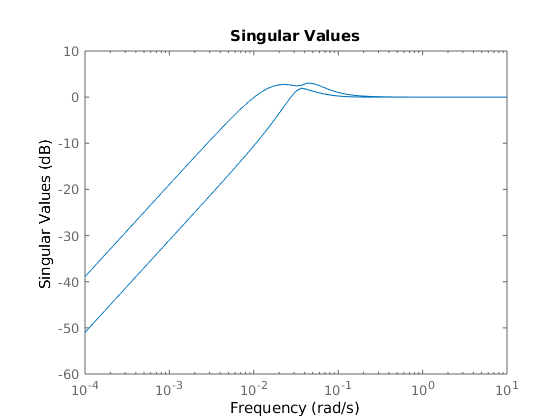



S=inv(eye(2)+L);
S=minreal(S);
T=inv(eye(2)+L)*L;
T=minreal(T);

sigma(S);

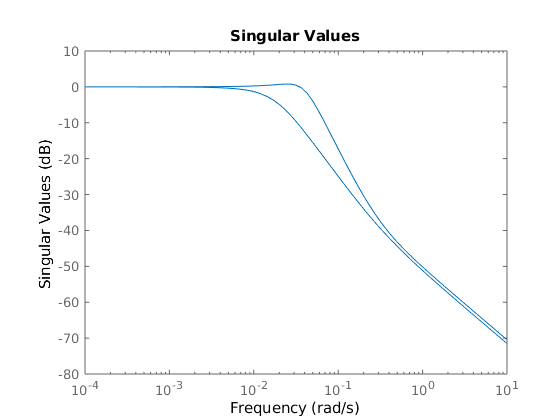

sigma(T);


stepinfo(T)

ans = 2×2 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


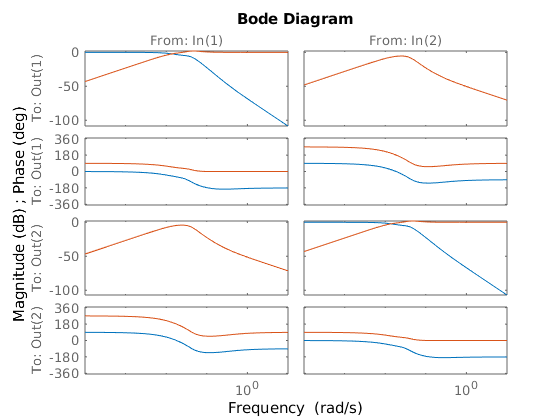


bode(T)
hold on 
bode(S)
hold off

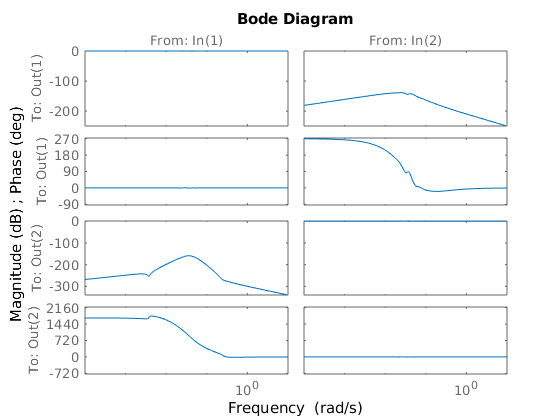


bode(S+T)

## 3.2.3

%closedloop 